%Her er et kort script der importerer en af trace filerne
%fra DJI Assistant 2, og henter X, Y og Z koordinater.

%Importer data
[A] = importdata("trace.txt")

A = 1333×1 cell array
    {'[14:20:31.550]→x:0.000000,y:0.000000,z:0.100000'}
    {'[14:20:31.580]→x:0.000000,y:0.000000,z:0.100000'}
    {'[14:20:31.610]→x:0.000000,y:0.000000,z:0.100000'}
    {'[14:20:31.640]→x:0.000000,y:0.000000,z:0.100000'}
    {'[14:20:31.670]→x:0.000000,y:0.000000,z:0.100000'}
    {'[14:20:31.700]→x:0.000000,y:0.000000,z:0.100000'}
    {'[14:20:31.730]→x:0.000000,y:0.000000,z:0.100000'}
    {'[14:20:31.760]→x:0.000000,y:0.000000,z:0.100000'}
    {'[14:20:31.790]→x:0.000000,y:0.000000,z:0.100000'}
    {'[14:20:31.820]→x:0.000000,y:0.000000,z:0.100000'}
    {'[14:20:31.850]→x:0.000000,y:0.000000,z:0.100000'}
    {'[14:20:31.880]→x:0.000000,y:0.000000,z:0.100000'}
    {'[14:20:31.910]→x:0.000000,y:0.000000,z:0.100000'}
    {'[14:20:31.940]→x:0.000000,y:0.000000,z:0.100000'}
    {'[14:20:31.970]→x:0.000000,y:0.000000,z:0.100000'}
    {'[14:20:32.000]→x:0.000000,y:0.000000,z:0.100000'}
    {'[14:20:32.030]→x:0.000000,y:0.000000,z:0.100000'}
    {'[14:20:32.060]→x:0.0

%Sorterer i tidselement of dataelement
[B] = split(A,"]")

B = 1333×2 cell array
    {'[14:20:31.550'}    {'→x:0.000000,y:0.000000,z:0.100000'}
    {'[14:20:31.580'}    {'→x:0.000000,y:0.000000,z:0.100000'}
    {'[14:20:31.610'}    {'→x:0.000000,y:0.000000,z:0.100000'}
    {'[14:20:31.640'}    {'→x:0.000000,y:0.000000,z:0.100000'}
    {'[14:20:31.670'}    {'→x:0.000000,y:0.000000,z:0.100000'}
    {'[14:20:31.700'}    {'→x:0.000000,y:0.000000,z:0.100000'}
    {'[14:20:31.730'}    {'→x:0.000000,y:0.000000,z:0.100000'}
    {'[14:20:31.760'}    {'→x:0.000000,y:0.000000,z:0.100000'}
    {'[14:20:31.790'}    {'→x:0.000000,y:0.000000,z:0.100000'}
    {'[14:20:31.820'}    {'→x:0.000000,y:0.000000,z:0.100000'}
    {'[14:20:31.850'}    {'→x:0.000000,y:0.000000,z:0.100000'}
    {'[14:20:31.880'}    {'→x:0.000000,y:0.000000,z:0.100000'}
    {'[14:20:31.910'}    {'→x:0.000000,y:0.000000,z:0.100000'}
    {'[14:20:31.940'}    {'→x:0.000000,y:0.000000,z:0.100000'}
    {'[14:20:31.970'}    {'→x:0.000000,y:0.000000,z:0.100000'}
    {'[14:20:32.000'}    {'→x:0.0

%Smider data væk, fjerner bracket fra tid
B = split(B(:,1),"[")

B = 1333×2 cell array
    {0×0 char}    {'14:20:31.550'}
    {0×0 char}    {'14:20:31.580'}
    {0×0 char}    {'14:20:31.610'}
    {0×0 char}    {'14:20:31.640'}
    {0×0 char}    {'14:20:31.670'}
    {0×0 char}    {'14:20:31.700'}
    {0×0 char}    {'14:20:31.730'}
    {0×0 char}    {'14:20:31.760'}
    {0×0 char}    {'14:20:31.790'}
    {0×0 char}    {'14:20:31.820'}
    {0×0 char}    {'14:20:31.850'}
    {0×0 char}    {'14:20:31.880'}
    {0×0 char}    {'14:20:31.910'}
    {0×0 char}    {'14:20:31.940'}
    {0×0 char}    {'14:20:31.970'}
    {0×0 char}    {'14:20:32.000'}
    {0×0 char}    {'14:20:32.030'}
    {0×0 char}    {'14:20:32.060'}
    {0×0 char}    {'14:20:32.102'}
    {0×0 char}    {'14:20:32.129'}
    {0×0 char}    {'14:20:32.186'}
    {0×0 char}    {'14:20:32.188'}
    {0×0 char}    {'14:20:32.212'}
    {0×0 char}    {'14:20:32.240'}
    {0×0 char}    {'14:20:32.270'}
    {0×0 char}    {'14:20:32.301'}
    {0×0 char}    {'14:20:32.330'}
    {0×0 char}    {'14:20:32.360'

%Beholder kun tid
t = B(:,2)

t = 1333×1 cell array
    {'14:20:31.550'}
    {'14:20:31.580'}
    {'14:20:31.610'}
    {'14:20:31.640'}
    {'14:20:31.670'}
    {'14:20:31.700'}
    {'14:20:31.730'}
    {'14:20:31.760'}
    {'14:20:31.790'}
    {'14:20:31.820'}
    {'14:20:31.850'}
    {'14:20:31.880'}
    {'14:20:31.910'}
    {'14:20:31.940'}
    {'14:20:31.970'}
    {'14:20:32.000'}
    {'14:20:32.030'}
    {'14:20:32.060'}
    {'14:20:32.102'}
    {'14:20:32.129'}
    {'14:20:32.186'}
    {'14:20:32.188'}
    {'14:20:32.212'}
    {'14:20:32.240'}
    {'14:20:32.270'}
    {'14:20:32.301'}
    {'14:20:32.330'}
    {'14:20:32.360'}
    {'14:20:32.390'}
    {'14:20:32.420'}



%Splitter A på ny, for data
[B] = split(A,[":",","])

B = 1333×8 cell array
    {'[14'}    {'20'}    {'31.550]→x'}    {'0.000000'}    {'y'}    {'0.000000'}    {'z'}    {'0.100000'}
    {'[14'}    {'20'}    {'31.580]→x'}    {'0.000000'}    {'y'}    {'0.000000'}    {'z'}    {'0.100000'}
    {'[14'}    {'20'}    {'31.610]→x'}    {'0.000000'}    {'y'}    {'0.000000'}    {'z'}    {'0.100000'}
    {'[14'}    {'20'}    {'31.640]→x'}    {'0.000000'}    {'y'}    {'0.000000'}    {'z'}    {'0.100000'}
    {'[14'}    {'20'}    {'31.670]→x'}    {'0.000000'}    {'y'}    {'0.000000'}    {'z'}    {'0.100000'}
    {'[14'}    {'20'}    {'31.700]→x'}    {'0.000000'}    {'y'}    {'0.000000'}    {'z'}    {'0.100000'}
    {'[14'}    {'20'}    {'31.730]→x'}    {'0.000000'}    {'y'}    {'0.000000'}    {'z'}    {'0.100000'}
    {'[14'}    {'20'}    {'31.760]→x'}    {'0.000000'}    {'y'}    {'0.000000'}    {'z'}    {'0.100000'}
    {'[14'}    {'20'}    {'31.790]→x'}    {'0.000000'}    {'y'}    {'0.000000'}    {'z'}    {'0.100000'}
    {'[14'}    {'20'}    {'31.820

%Omdanner strings til doubles for X Y og Z
B = str2double([B(:,4) B(:,6) B(:,8)])

B =          0         0    0.1000
         0         0    0.1000
         0         0    0.1000
         0         0    0.1000
         0         0    0.1000
         0         0    0.1000
         0         0    0.1000
         0         0    0.1000
         0         0    0.1000
         0         0    0.1000


% Laver B om til en tabel
T = array2table(B);
%Giver variabel navne til kolonnerne
T.Properties.VariableNames(1:3) = {'x','y','z'}

T = 1333×3 table
    x    y     z 
    _    _    ___

    0    0    0.1
    0    0    0.1
    0    0    0.1
    0    0    0.1
    0    0    0.1
    0    0    0.1
    0    0    0.1
    0    0    0.1
    0    0    0.1
    0    0    0.1
    0    0    0.1
    0    0    0.1
    0    0    0.1
    0    0    0.1
    0    0    0.1
    0    0    0.1


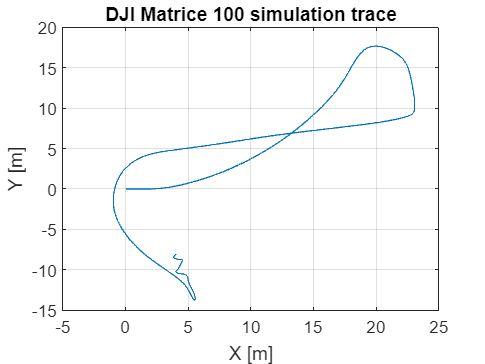

%T.Properties.VariableNames(1:3) = {'x','y','z'}

plot(T.x,T.y)
grid on
xlabel("X [m]");
ylabel("Y [m]");
title("DJI Matrice 100 simulation trace");